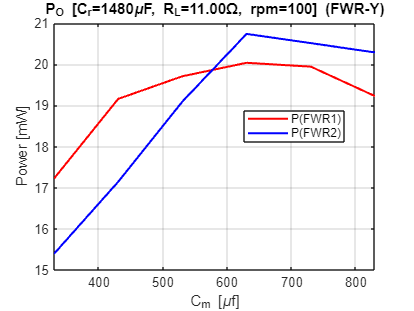


% Dati misurati (Y1_100rpm.csv, Y2_100rpm.csv - tabella "R = 11 Ohm"):
% sweep del condensatore di compensazione C_m, R_L e rpm fissi, per i due bridge FWR-Star.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 11;           % Ohm - carico fisso durante lo sweep
rpm_b1 = 100;       % rpm fisso durante lo sweep

C_L = [330 430 530 630 730 830]*1e-6;   % F - condensatore di compensazione C_m (asse x)

Po_b1_mW = [17.2212 19.1567 19.7061 20.0332 19.9400 19.2240];
Pi_b1_mW = [50.7094 54.3784 54.7050 54.9546 55.4711 54.4002];

Po_b2_mW = [15.3927 17.1437 19.0916 20.7355 20.5111 20.2845];
Pi_b2_mW = [47.3969 51.6100 55.3375 57.5332 57.8992 57.4816];

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;


figure;
plot(C_L*1e6, P_real_b1*1000, 'r-', 'LineWidth', 1.5);hold on;
plot(C_L*1e6, P_real_b2*1000, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (FWR-Y)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
legend(["P(FWR1)", "P(FWR2)"], "Location", "best")
hold off;

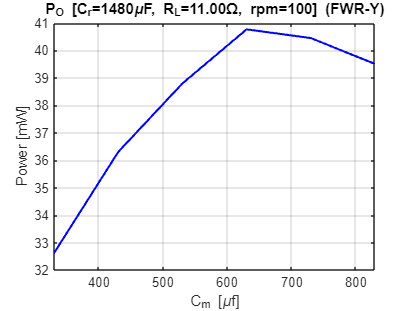



figure;
plot(C_L*1e6, (P_real_b1+P_real_b2)*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (FWR-Y)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
hold off;